clearvars; close all; clc;

# Semi inductance

JVsound, J.G. Vermond

disp(datetime("today"))

   25-Feb-2026



We try to obtain a good fit method for the following diagram, where semi-inductance is present.

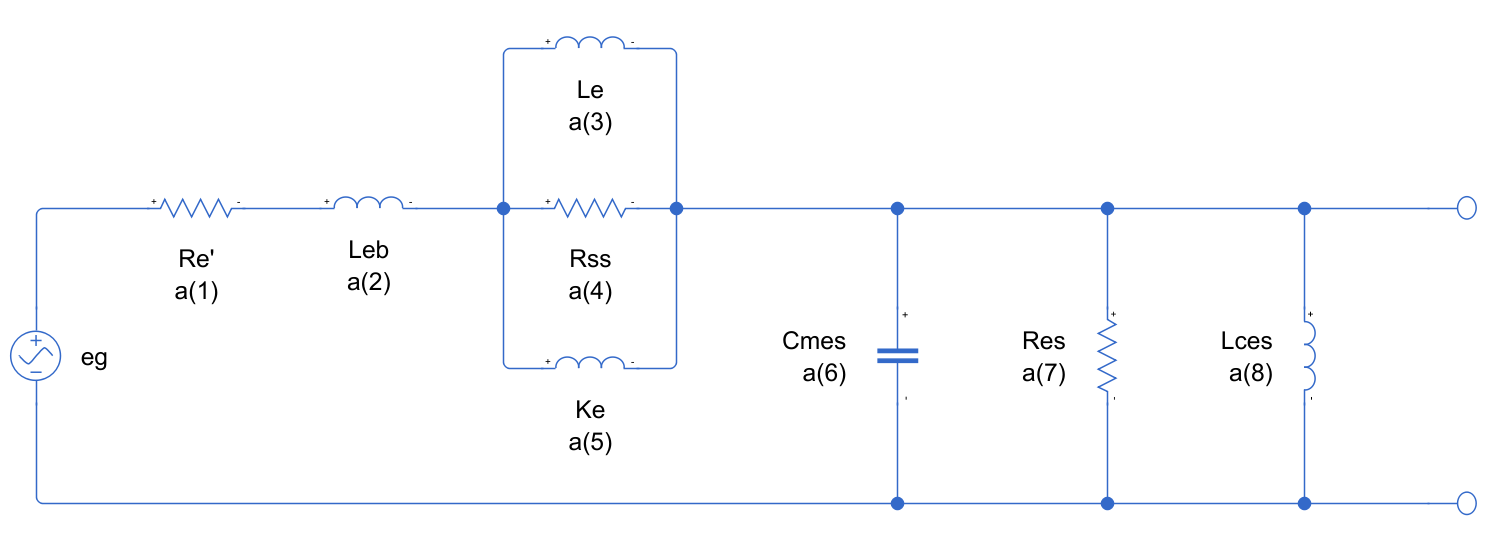

The total electric impedance $Z_e$ is:


$$Z_e = R_e\prime + j\omega L_{eb} + \left[\frac{1}{j\omega L_e}+\frac{1}{R_{es}}+\frac{1}{j\omega K_e} \right]^{-1} + \left[j\omega C_{mes} + \frac{1}{R_{es}} + \frac{1}{j\omega L_{ces}}\right]^{-1}
$$


First we want to see if this equation is capable of plotting a 'correct' impedance curve, by using a predefined example for the B&C 18DS115-8:

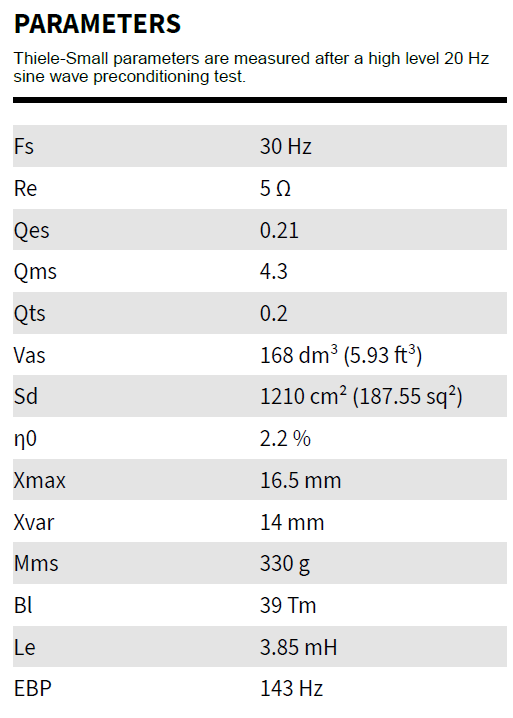

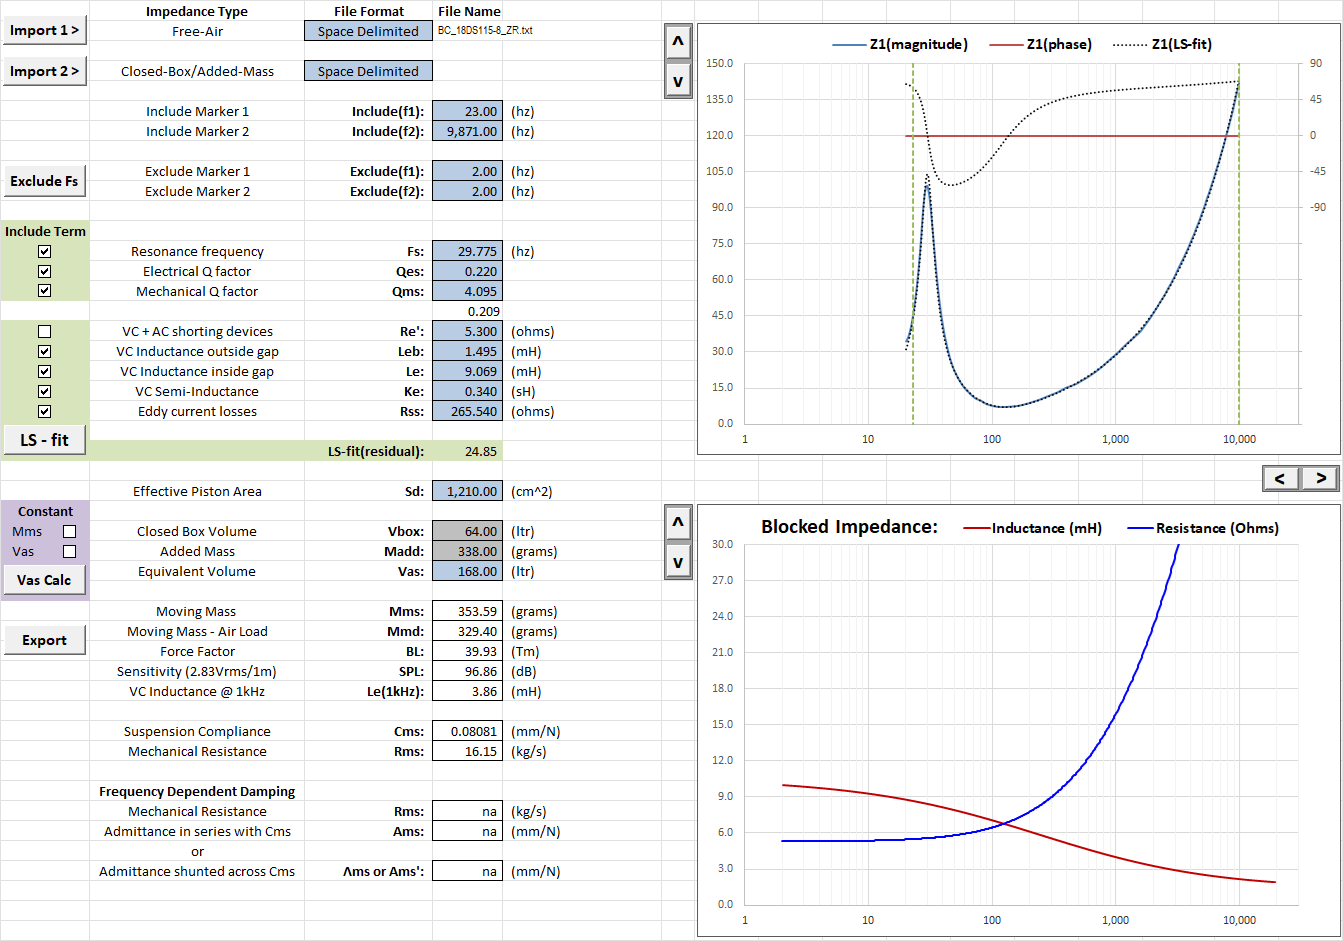

We define a speaker object:

bc18ds115_8			= speaker.woofer;

bc18ds115_8.brand	= "B&C";
bc18ds115_8.model	= "18DS115-8";
bc18ds115_8.size	= "18";
bc18ds115_8.re		= 5.3;
bc18ds115_8.qes		= .22;
bc18ds115_8.qms		= 4.09;
bc18ds115_8.fs		= 29.77;
bc18ds115_8.sd		= 1210e-4;
bc18ds115_8.vas		= 168e-3;
bc18ds115_8.le		= 3.87e-3;
bc18ds115_8.xmax	= 16.5e-3;
bc18ds115_8.paes	= 0

bc18ds115_8 =   woofer with properties:

    brand: "B&C"
    model: "18DS115-8"
     size: 18
       re: 5.3000
      qes: 0.2200
      qms: 4.0900
       fs: 29.7700
       sd: 0.1210
      vas: 0.1680
       le: 0.0039
     xmax: 0.0165
     paes: 0
      qts: 0.2088
      cms: 8.1794e-05
      kms: 1.2226e+04
      mms: 0.3494
      mmd: 0.3018
      rms: 15.9807
       bl: 39.6813
        a: 0.1963


The semi-inductance parameters provided by Bolsert (diyaudio.com) are:

Rea			= 5.3;
Leb			= 1.5e-3;
Le			= 9.07e-3;
Ke			= 0.340e-3;
Rss			= 265.54;

With this data we should be able to plot the electric impedance. We define an anonymous function where vector $a$ represents all lumped element values:


$$Z_e = a_1 + j\omega a_2 + \left[ \frac{1}{j\omega a_3} + \frac{1}{a_4} + \frac{1}{j\omega a_5} \right]^{-1} + \left[j\omega a_6 + \frac{1}{a_7} + \frac{1}{j\omega a_8}\right]^{-1}$$


% The function for Ze with all 8 unknowns we call f1:
f1		= @(a,x) a(1) + 1i*x*a(2) + (1./(1i*x*a(3)) + 1/a(4) + 1./(1i*x*a(5))).^-1 + (1i*x*a(6) + 1/a(7) + 1./(1i*x*a(8))).^-1;

$a_6$, $a_7$ and $a_8$ are unknown but can be calculated using the speaker object:

% a6 = Cmes
a6		= bc18ds115_8.mms / bc18ds115_8.bl^2;
% a7 = Res
a7		= bc18ds115_8.bl^2 / bc18ds115_8.rms;
% a8 = Lces
a8		= bc18ds115_8.bl^2 * bc18ds115_8.cms;

We can now create the complete $a$ array:

a		= [Rea; Leb; Le; Rss; Ke; a6; a7; a8];

We evaluate the function over a frequency range:

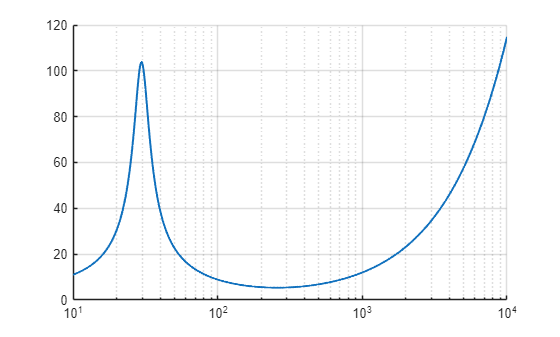

% Frequency vector:
f			= logspace(1,4,1e3);
x			= 2*pi*f;

% Evaluate f1:
f1out		= f1(a,x);

% Figure:
fig1		= figure;
ax1			= axes(fig1); hold on; grid on;
ax1.XScale	= "log";
% ax1.YScale	= "log";

plot(ax1,f,abs(f1out),LineWidth=1.5)

What do we want to do next:

- Is it possible to easily fix a parameter in fminsearch? Or do I need fmincon?

- Can we get fminsearch or fmincon to fit the curve properly?

We try fminsearch and fmincon for a simple function:

% For a simple quadratic function we try to find the minimum value:
fex			= @(x) 8*x + x.^2 - 10;
% x range:
x			= -10:10;

% Find x value for minimum value:
xval1		= fminsearch(fex,0)

xval1 = -4.0000

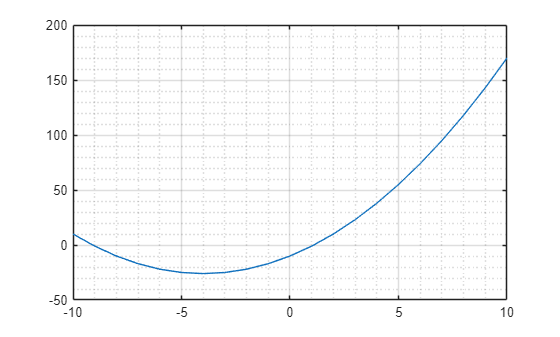

figure
plot(x,fex(x)); grid on; grid minor;

It appears fmincon and fminunc requires the optimization toolbox, so we are left with fminsearch.

We continue our example with the electrical impedance, and see if we can get a good parameter fit for it. The number of parameters is already 5. We change the parameter symbol from $a$ to $x$ to comply with Matlab's examples.


$$Z_e = x_1 + j\omega x_2 + \left[ \frac{1}{j\omega x_3} + \frac{1}{x_4} + \frac{1}{j\omega x_5} \right]^{-1}$$


% Create anonymous function:
ze		= @(w,x) x(1) + 1i*w*x(2) + (1./(1i*w*x(3)) + 1/x(4) + 1./(1i*w*x(5))).^-1;

% Evaluate for following w and x:
w		= logspace(1,4,1e3) * 2*pi;
x		= [Rea; Leb; Le; Rss; Ke];

zeval	= ze(w,x);

figure;
semilogx(w,abs(zeval)); hold on;

And now, if we do not know vector $x$, can we get a good estimate with random starting values?

% x0 start values:
x0 = ones(5,1);
% Objective function:
obj_fun = @(x) norm((ze(w,x)-zeval));
% Evaluate function:
obj_fun(x0)

ans = 5.3516e+05

[xit1,resmod,~,it1]	= fminsearch(obj_fun,x0)

xit1 =     1.3844
    0.0018
    1.1818
    0.9841
    1.2146


resmod = 96.7809

it1 = struct with fields:
    iterations: 113
     funcCount: 214
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


zeval1	= ze(w,xit1);

semilogx(w,abs(zeval1),"--")

Now with other $x_0$:

x0	= [5.3; 1e-3; 1e-3; 1; 1e-3];

[xit2,resmod,~,it2]	= fminsearch(obj_fun,x0)

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.035710 



xit2 =     5.3002
    0.0015
    0.0493
  219.3426
    0.0003


resmod = 0.0357

it2 = struct with fields:
    iterations: 642
     funcCount: 1001
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Exiting: Maximum number of function evaluations has been exceeded↵         - increase MaxFunEvals option.↵         Current function value: 0.035710 ↵'


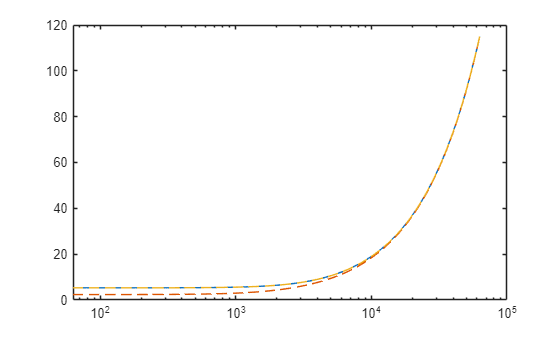


plot(w,abs(ze(w,xit2)),LineStyle="--")

This seems to work quite well. What if we add the other parameters, as knowns:


$$Z_e = a_1 + j\omega a_2 + \left[ \frac{1}{j\omega a_3} + \frac{1}{a_4} + \frac{1}{j\omega a_5} \right]^{-1} + \left[j\omega C_{mes} + \frac{1}{R_{es}} + \frac{1}{j\omega L_{ces}}\right]^{-1}$$


Cmes	= a6;
Res		= a7;
Lces	= a8;

% Define new anonymous function:
ze2		= @(w,x) x(1) + 1i*w*x(2) + (1./(1i*w*x(3)) + 1/x(4) + 1./(1i*w*x(5))).^-1 + (1i*w*Cmes + 1/Res + 1./(1i*w*Lces)).^-1;


% x0 start values:
x0 = ones(5,1);
% Objective function:
obj_fun = @(x) norm((ze2(w,x)-zeval));
% Evaluate function:
obj_fun(x0)

ans = 5.3515e+05

[xit,resmod,~,it]	= fminsearch(obj_fun,x0)

xit =     1.2836
    0.0018
    1.3839
    0.9844
    1.1804


resmod = 689.3015

it = struct with fields:
    iterations: 105
     funcCount: 203
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


figure;
semilogx(w,abs(f1(a,w)),LineWidth=1.5); hold on; grid on;
plot(w,abs(ze2(w,xit(1:5))),LineStyle="--"); grid on;

Now with other start values:

x0		= [5.3 1e-3 1e-3 1 1e-3]';

[xit2,resmod,~,it]	= fminsearch(obj_fun,x0)

xit2 =   -12.2948
    0.0018
    0.0676
   18.3981
    0.0704


resmod = 631.8238

it = struct with fields:
    iterations: 330
     funcCount: 541
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


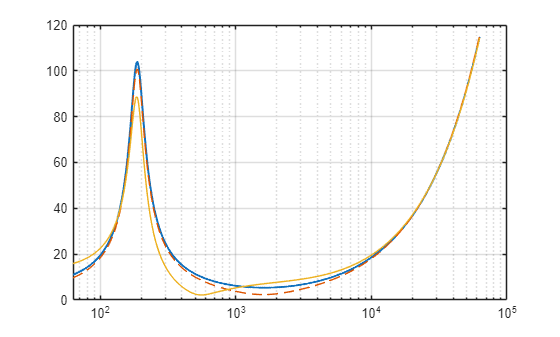

plot(w,abs(ze2(w,xit2)))

Can we make something so we can modify the curve ourself by a Control object?

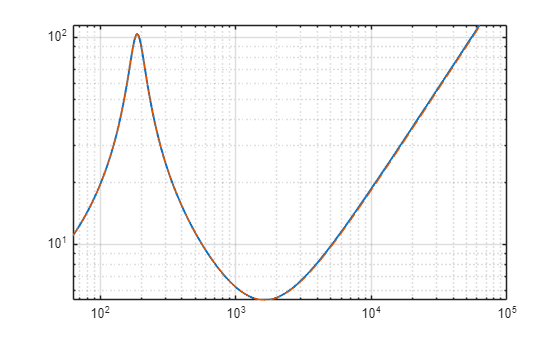

figure;
loglog(w,abs(f1(a,w)),LineWidth=1.5); hold on; grid on;

Re = 5.3;
Leb = 0.0018;
Le = 0;
Rss = 0;
Ke = 0;
% x0 fit:
x0 = [Re Leb Le Rss Ke]';
zeval	= ze2(w,x0);
plot(w,abs(zeval),LineStyle="--");

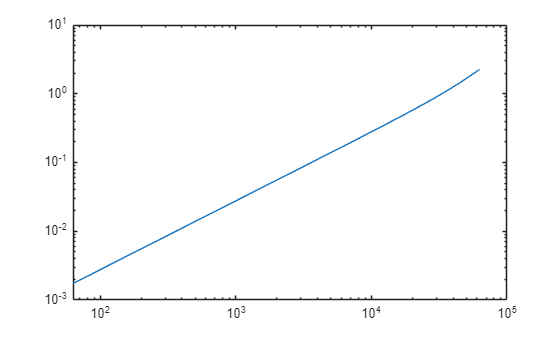

figure
loglog(w,abs(f1out - zeval))